# **Golden Section Search **

The Golden Section Search method is used to find the maximum or minimum of a unimodal function. (A unimodal function contains only one minimum or maximum on the interval [a,b].).This method is an efficient way to progressively reduce the interval locating maximum or minimum.This program will be used to find the maximum value of a unimodal function.

## Golden Ratio:

The golden ratio *(symbol is the Greek letter "phi" ) *is a special number approximately equal to 1.618.It appears many times in geometry, art, architecture and other areas. We find the golden ratio when we divide a line into two parts so that:

the whole length divided by the long part

***is also equal to***

the long part divided by the short part

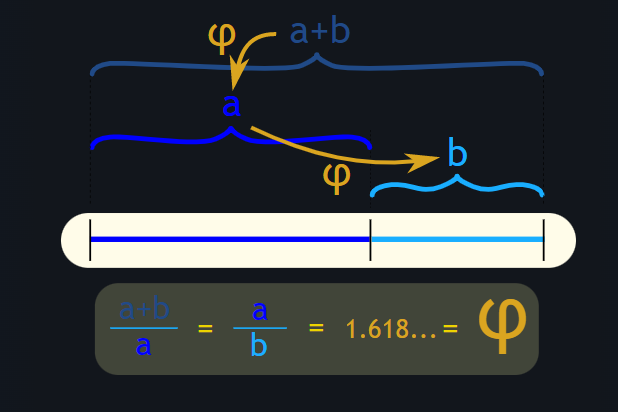

## **Procedure :**

The method starts with two initial guesses, $x_l$ and $x_u$, that bracket one local extremum of f(x). Next, two interior points $x_1$and $x_2$ are chosen according to the **reciprocal of golden ratio**,

### 
$$d=\frac{\surd 5-1}{2}\left({x_u -x}_l \right)$$


### $x_1$=$x_l +d$

### 
$$x_2 =x_u -d$$


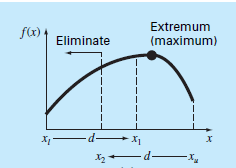

The function is evaluated at these two interior points. Two results can occur:

- If  **f(**$x_1$**) > f(**$x_2$**)**, then the domain of x to the left of $x_2$, from $x_l$ to $x_2$, can be eliminated because it does not contain the maximum. For this case, $x_2$ becomes the new $x_l$ for the next round.

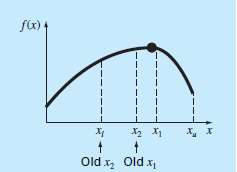

                                   $\Longrightarrow$The old $x_1$ becomes the new $x_2$.

                                   $\Longrightarrow$To complete the algorithm, we now only need to determine the new $x_1$. This is done with the same proportionality as before, 

                                    
$$x_1 =x_l +\frac{\surd 5-1}{2}\left({x_u -x}_l \right)$$


- If **f(**$x_2$**) > f(**$x_1$**)**, then the domain of x to the right of $x_1$, from $x_1$ to $x_u$ would have been eliminated. In this case, $x_1$ becomes the new $x_u$ for the next round.

                                   $\Longrightarrow$The old $x_2$ becomes the new $x_1$.

                                   $\Longrightarrow$To complete the algorithm, we now only need to determine the new $x_2$. This is done with with the same proportionality as before, 

                                    
$$x_2 =x_u -\frac{\surd 5-1}{2}\left({x_u -x}_l \right)$$


### Step 1 : Defining the function 

First step of this method is to define the function and it's lower bound and upper bound which is **a** and **b**.For ensuring the accuracy of the optimum value, we have to define the accuracy(**accuracy**) .

Here we will take function as input from user which will be treated as a string and stored into  **f_input** variable.Using inline function (ignoring warning )  we have turned it into a vector which can be calculated by Matlab.

Here we have defined accuracy as approximate relative error which can be representated as :

#### 
$$\textrm{Error}=\left(1-\textrm{Reciprocal}\;\textrm{of}\;\textrm{Golden}\;\textrm{Ratio}\right)|\frac{x_u -x_l }{x_{\textrm{opt}} }|$$


For simplification of our calculation we didnot converted the accuracy into % .So if we want 1% accuracy here the value of accuracy will be 0.001

f_input = input("Enter f(x) = ","s");           %Function of variable x
f = inline(f_input);                            %using inline function
x_l = input ( "Value of lowerbound =");
x_u = input ( "Value of upperbound =");
accuracy = input ( "Value of required accuracy  =");

### Step 2 : Defining Constant 

For performing the golden section search we have to define the reciprocal of golden ratio. Using the **reciprocal of golden** ratio we will calculate the value of **d** to find out the interior point between the upper bound and lower bound.

r_golden_ratio = double((sqrt(5)-1)/2);
d=r_golden_ratio*(x_u-x_l);

### **Step 3 : Finding interiror point** 

In this step, we will find two  interior point **x1** and **x2** using the value of **d **and calculate the funcation value of this two point and store it tinto **f_x1** and **f_x2**

x1=x_l +d;             % computing interiror  values
x2 = x_u - d;

f_x1=f(x1);            % computing functional values in interiror points
f_x2=f(x2);

### Step 4 :Comapring two functional value at interiror points 

If the functional value at upper and lower bound is same than the function has maximum value at any of the interiror point.

if f_x1 == f_x2 
    fprintf("The function has maximum value at point %f and which is %f",x1,f_x1);
end

### Step 5 : Error and Iteration 

Our iteration process will continue untill the **accuracy** exceeds **error**.We have initialize the **error** value as **infinity** and at the beginning the **iteration** value is 1. 

### 
$$\textrm{Error}=\left(1-\textrm{Reciprocal}\;\textrm{of}\;\textrm{Golden}\;\textrm{Ratio}\right)|\frac{x_u -x_l }{x_{\textrm{opt}} }|$$


error = inf;
iteration = 1;

### Step 6 : Iterating for the Maximum Value 

For iteration process we will use while loop as our iteration will continue untill we achieve our required accuracy.We will check three condition in iteration process by using five variable (**x_u, x_l,x1,x2,x_opt**). According to the condition our variable will be substitute by another variable . When we will substitute one variable we will obviously substitute its functional value(**f_l,f_u,f_x1,f_x2,f_opt**).

####  1. **f_x1 > f_x2** : If functional value at $x_1$ point is greater  than $x_2$ then 

- $x_2$ will be our new lowerbound 

- Our new $x_2$ will be $x_1$

- Our new $x_1$ will be calculated from Reciprocal of Golden Ratio and difference between upper and lowerbound and added with $x_l$

- Functional value at $x_1$ will be our optimum value

#### 2. **f_x2 > f_x1** : If functional value at $x_1$ point is less than $x_2$ then

- $x_1$ will be our new upperbound 

- Our new $x_1$ will be $x_2$

- Our new $x_2$ will be calculated from Reciprocal of Golden Ratio and difference between upper and lowerbound and substract from $x_u$

- Functional value at $x_2$ will be our optimum value.

#### 3. **f_x2 == f_x1** : If functional value at $x_1$ point is equal to  $x_2$ then

- We have find our optimum value and we will terminate the loop by using **return** statement.

Our final task in while loop is to update the value of **error** in order to terminate the while loop. As we have to calculate the error by dividing **x_opt** so we will chack is the value of **x_opt** zero or not.Then we will upadte the error value using the formula :


$$\textrm{Error}=\left(1-\textrm{Reciprocal}\;\textrm{of}\;\textrm{Golden}\;\textrm{Ratio}\right)|\frac{x_u -x_l }{x_{\textrm{opt}} }|$$


while (error > accuracy)
    
    %Comparing the functional value of interiror points
    if f_x1 > f_x2 
        
        
        % X2 will be our new lower bound
        x_l = x2 ;
        f_l = f(x_l);
        
        %Our new X2 will be X1 
        x2 = x1 ;
        f_x2 = f_x1 ;
        
        %Our new X1 will be calculated from Golden Ratio and difference between upper and lowerbound
        x1 = x_l + r_golden_ratio * ( x_u - x_l) ;
        x_opt = x1;
        
       %Functional value at x1 will be our optimum value
       f_x1 = f(x1);
       f_opt =f_x1;
    end   
    
    %Comparing the functional value of interiror points
    if f_x2 > f_x1 
        
        % X1 will be our new upper bound 
        x_u = x1;
        f_u = f(x_u);
        
        % 0ur new X1 will be X2
        x1 = x2;
        f_x1= f_x2;
        
        %Our new X2 will be calculated from Golden Ratio and difference between upper and lowerbound  
        x2 = x_u - r_golden_ratio * ( x_u - x_l);
        x_opt=x2;
        
        %Functional value at x2 will be our optimum value 
        f_x2 = f(x2);
        f_opt = f_x2;
        
    end     
    
    %Exiting loop if two interior point has same functional value 
    if f_x2 == f_x1
            return
            
    end
    
    % determinig if converged 
    if x_opt ~= 0
        
        %updating the error value 
        error = (1-r_golden_ratio) * abs ( x_l-x_u) /(x_opt);
        
        %Increasing the value of iteration
        iteration = iteration + 1 ;
    end
    
end 

**Step 7 : Printing  Maximum Value and Number Of Iteration**

Finally we will print number of iteration and maximum value of the function.

fprintf("The function has maximum value at point %f which is %f",x_opt,f_opt);
fprintf("Number of iteration needed to find maximum value is %d",iteration);
